clear all


MC = readtable('monthly reconsMC.xlsx','Sheet','84slope','VariableNamingRule','preserve');
d18Osw_centred = MC.d18Osw;
d18Osw_centred_l =MC.("2.5cl_1");
d18Osw_centred_u =MC.("97.5cl_1");
errordate = vertcat(MC.Date,flipud(MC.Date));
errd18Osw_MC95 = vertcat(d18Osw_centred_u,flipud(d18Osw_centred_l));
gap = (10:12:4030)';
yr = (1672:2006)';
Ad18OswC = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=d18Osw_centred(gap(i):(gap(i+1)-1));
    Ad18OswC(i) = mean(t,'omitnan');
i=i+1;
end

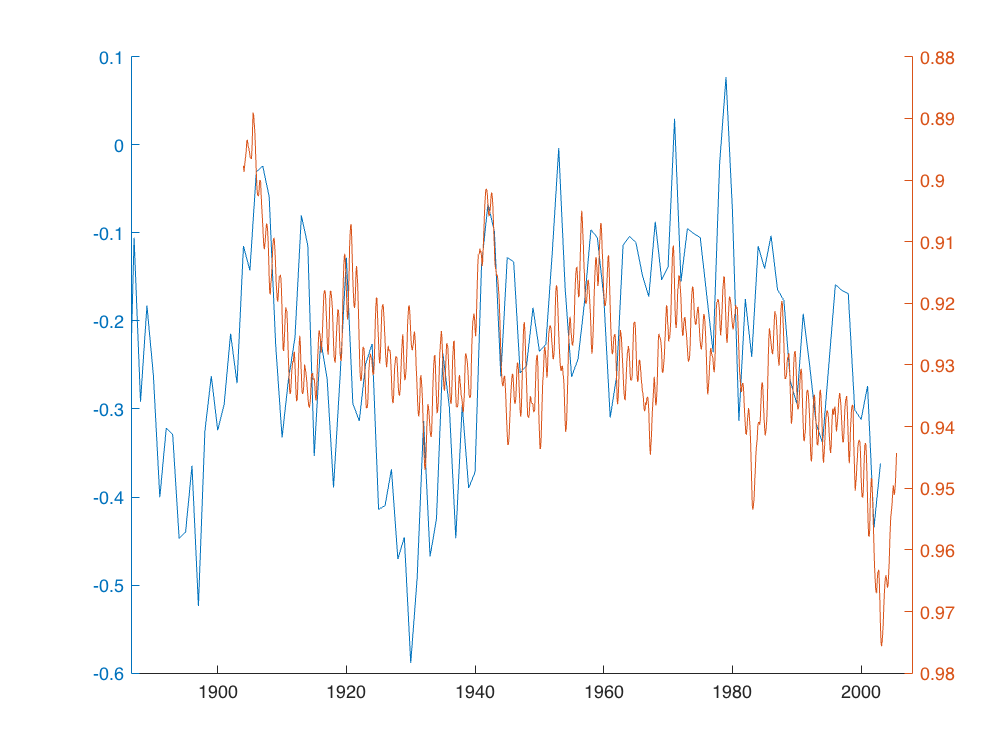

GB = readtable('GBGrove.xlsx');
clf
hold on
yyaxis left
plot(yr-3,Ad18OswC)
yyaxis right
set(gca,'ydir','reverse')
plot(GB.Year,movmean(GB.MAS,31))
set(gca,'xlim',[1886.583 2008])

coralSST_centred = MC.SST;
coralSST_centred_l=MC.("2.5cl");
coralSST_centred_u=MC.("97.5cl");
BMerr90 = (coralSST_centred_u - coralSST_centred_l)/2;

TSSTC = readtable('SSTA.xlsx','Sheet','SWIOSSTA');
TSSTC.BMerr90 = (coralSST_centred_u - coralSST_centred_l)/2;
TSSTC.Mon = categorical(TSSTC.Mon);

Tsummer = vertcat(TSSTC((TSSTC.Mon=='1'),:),TSSTC((TSSTC.Mon=='2'),:),TSSTC((TSSTC.Mon=='3'),:),TSSTC((TSSTC.Mon=='12'),:));
Tsummer = sortrows(Tsummer,2);

Twinter = vertcat(TSSTC((TSSTC.Mon=='6'),:),TSSTC((TSSTC.Mon=='7'),:),TSSTC((TSSTC.Mon=='8'),:),TSSTC((TSSTC.Mon=='9'),:));
Twinter = sortrows(Twinter,2);
Twinter = Twinter(3:1342,:);
gap = (1:4:1341)';
yr = (1672:2006)';

ASSTC = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=coralSST_centred (gap(i):(gap(i+1)-1));
    ASSTC(i) = mean(t,'omitnan');
i=i+1;
end

ASSTC(45) = nan;
ASSTC(60:62) =nan;
[ASSTC,~] = fillmissing(ASSTC,"linear","SamplePoints",yr); %fill gap 
ASSTC_Err90 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=BMerr90(gap(i):(gap(i+1)-1));
    ASSTC_Err90(i) = rms(t,'omitnan');
i=i+1;
end

gap = (1:4:1341)';
yr_w = (1672:2006)';
winterSSTC = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.BM84(gap(i):(gap(i+1)-1));
    winterSSTC(i) = mean(t,'omitnan');
i=i+1;
end

winterSSTC(45) = nan;
winterSSTC(60:62) =nan;
[winterSSTC,~] = fillmissing(winterSSTC,"linear","SamplePoints",yr_w); %
winterSSTCerror90 = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.BMerr90(gap(i):(gap(i+1)-1));
    winterSSTCerror90(i) = rms(t,'omitnan');
i=i+1;
end

EDate = vertcat(yr,flipud(yr));
Err = vertcat(winterSSTC+winterSSTCerror90, flipud(winterSSTC-winterSSTCerror90));


IO2k = readtable('LIA.xlsx','Sheet','IO2k');

EP2k = readtable('LIA.xlsx','Sheet',"EP2k");

Ifaty = readtable('LIA.xlsx','Sheet','Ifaty');

Damassa = readtable('LIA.xlsx','Sheet','Damassa');



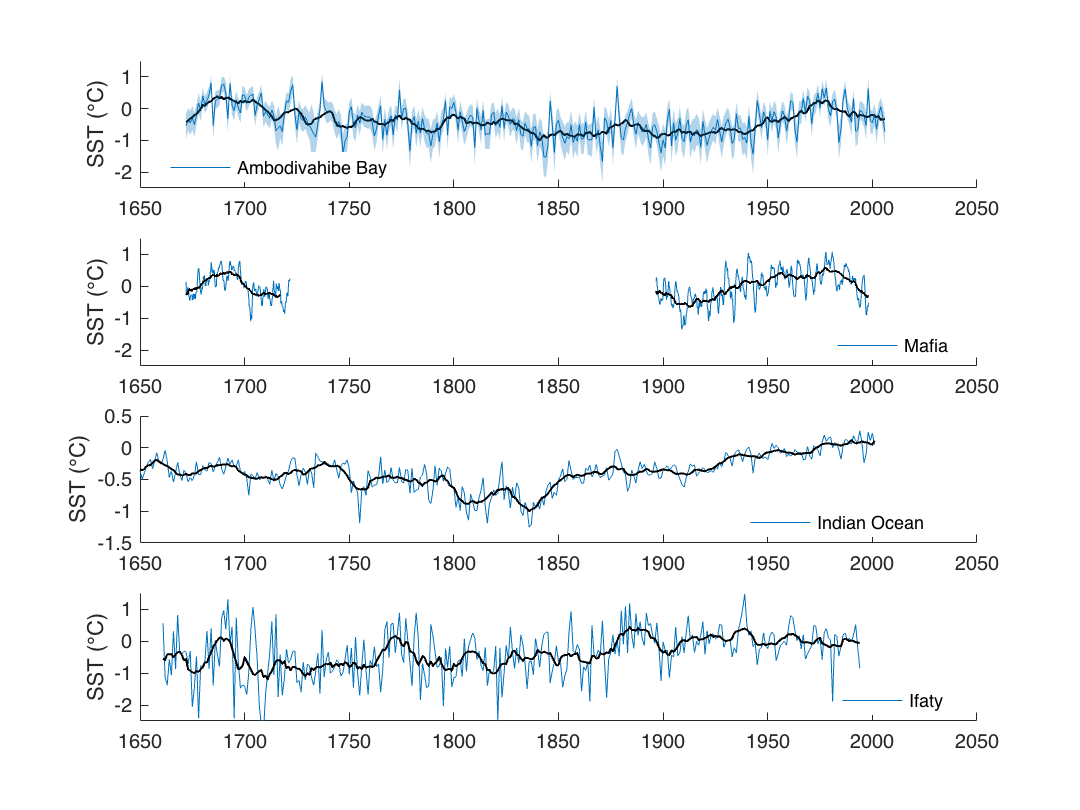

clf
subplot(4,1,1)
hold on 
plot(yr,winterSSTC)
plot(yr,movmean(winterSSTC,10),'LineWidth',1,'color',[0 0 0])
patch(EDate,Err,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.3)
set(gca,'XLim',[1650 2050])
set(gca,'YLim',[-2.5 1.5])
lg = legend('Ambodivahibe Bay');
set(lg,'box','off','Location','best')
ylabel('SST (°C)')

subplot(4,1,4)
plot(Ifaty.Year,Ifaty.IfatyCompositeSST)
hold on
plot(Ifaty.Year,movmean(Ifaty.IfatyCompositeSST,10),'LineWidth',1,'color',[0 0 0])
box off
set(gca,'XLim',[1650 2050])
set(gca,'YLim',[-2.5 1.5])
lg = legend('Ifaty');
set(lg,'box','off','Location','best')
ylabel('SST (°C)')

subplot(4,1,3)
hold on
plot(IO2k.age_CE,IO2k.sst_apr_mar_anom)
plot(IO2k.age_CE,movmean(IO2k.sst_apr_mar_anom,10),'LineWidth',1,'color',[0 0 0])
set(gca,'XLim',[1650 2050])
set(gca,'YLim',[-1.5 0.5])
lg = legend('Indian Ocean');
set(lg,'box','off','Location','best')
ylabel('SST (°C)')


subplot(4,1,2)
hold on
plot(Damassa.Old,movmean((Damassa.d18O-mean(Damassa.d18O,'omitnan'))/-0.22,6))
plot(Damassa.New,movmean((Damassa.d18Onew-mean(Damassa.d18Onew))/-0.22,12),'color',[0 0.4470 0.7410])
plot(Damassa.Old,movmean((Damassa.d18O-mean(Damassa.d18O,'omitnan'))/-0.22,60),'LineWidth',1,'color',[0 0 0])
plot(Damassa.New,movmean((Damassa.d18Onew-mean(Damassa.d18Onew))/-0.22,120),'LineWidth',1,'color',[0 0 0])
set(gca,'XLim',[1650 2050])
set(gca,'YLim',[-2.5 1.5])
lg = legend('Mafia');
set(lg,'box','off','Location','best')
ylabel('SST (°C)')